# Basic Matlab/LFP Stuff

Covers basic matlab usage and inspection of frequency content of LFPs.

Author: Brian Carson

Change Log:

3/2018: Created by Brian Carson

%%         new section shortcut
%          comment line
Fs=1000; % defines Fs ( sampling frequency )
f=1;
x=sin(((1:1/Fs:10)*2*pi)*5.5);
y=cos(((1:1/Fs:10)*2*pi)*60);

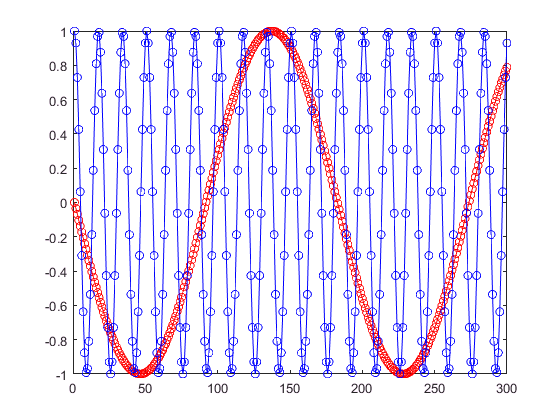

figure
plot(x(1:300),'ro-')
hold on % used for plot overlays/multiple plots in one figure
plot(y(1:300),'bo-')
hold off

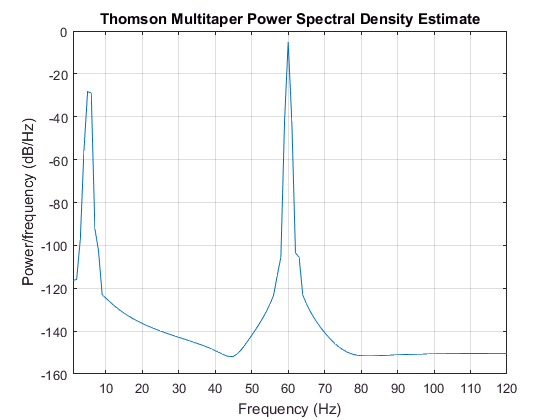

pmtm(x+y,[],1:120,Fs) % raw PSD via Thomson multitaper

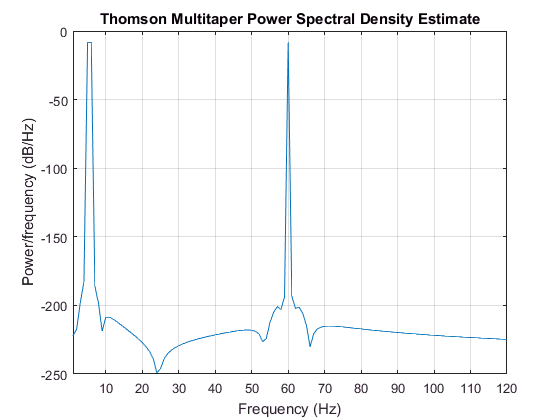

pmtm(x+y,8,1:120,Fs) % Via Thomson Multitaper w all arguments

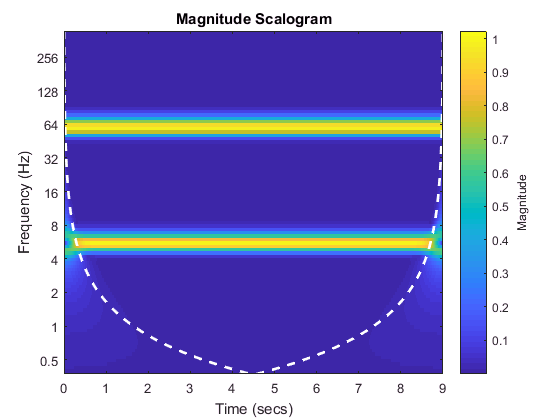

figure 
cwt(x+y,Fs)

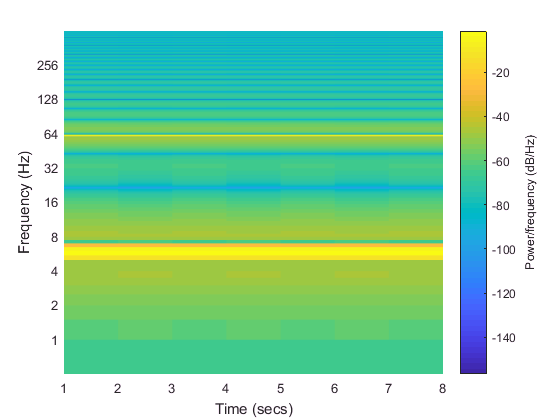

spectrogram(x+y,[],[],[],Fs,'yaxis')
s=spectrogram(x+y,[],[],[],Fs);
ax=gca;
ax.YScale='log';
grid(ax,'on')
set(ax,'YMinorTick','on','YTick', [1 2 4 8 16 32 64 128 256]);

Real LFP Data

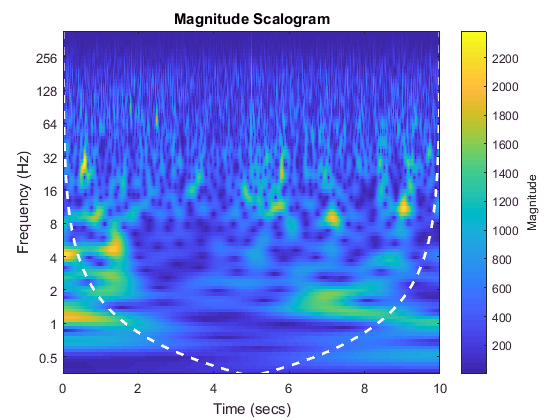

ev=4; % select event
trial=4; % select trial
win=5; % define +- window size
time=round((allts{1,4}(1)*Fs)-win):round((allts{1,4}(1)*Fs)+win); % time vector (rounding should be redundant after multiplication)
sig=allad{1}(time); % extract time vector from LFP
cwt(sig,1000) % TF content via wavelet

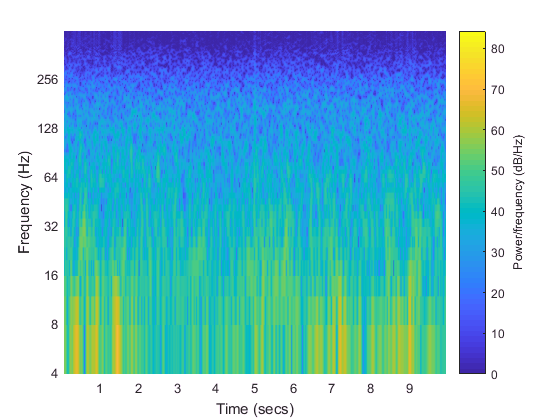

figure
spectrogram(sig,128,120,[],Fs,'yaxis'); % TF content via FFT
ax = gca;
ax.YScale = 'log';
grid(ax,'on');
% Set the remaining axes properties
set(ax,'CLim',[0 max(max(abs(s).^(-exp(1))))],'YMinorTick','on','YTick',...
    [1 2 4 8 16 32 64 128 256]);